# Displacement Sensor Calibration

load("gainData.mat");
% K Value: 2 (Set by course)
K = 2;
[dispCalibrCurve, dispCalibrGoodness] = fit(voltageCalibrationData, positionCalibrationData, 'poly1');
dispCalibrGain = dispCalibrCurve.p1; % mm/V
dispCalibrOffset = dispCalibrCurve.p2; % mm

## Uncertainty Calcs

dispSTD = dispCalibrGoodness.rmse; % mm
dispUncertainty = dispSTD.*K; % mm
fprintf("Prediction Interval (K = 2): %.4f mm\n", dispUncertainty);

Prediction Interval (K = 2): 1.0268 mm


## Visualizing Sensor Calibration

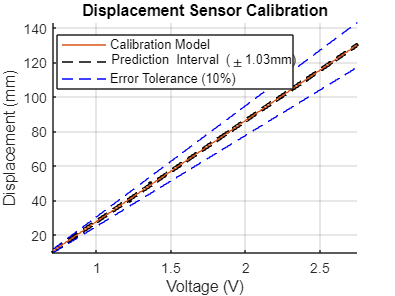

figure
hold on; grid on;
scatter(voltageCalibrationData, positionCalibrationData, 50, 'k.')
% Add Calibration Model
dispFitData = feval(dispCalibrCurve, voltageCalibrationData);
dispCalibrCurvePlot = plot(voltageCalibrationData, dispFitData);
% Add Prediction Interval
dispUncertaintyPlot = plot(voltageCalibrationData, dispFitData + dispUncertainty, 'k--');
plot(voltageCalibrationData, dispFitData - dispUncertainty, 'k--')
% Add Tolerance Interval (10%, set by client)
dispTolerancePlot = plot(voltageCalibrationData, dispFitData.*1.10, 'b--');
plot(voltageCalibrationData, dispFitData.*0.90, 'b--')
% Format Plot
legend([dispCalibrCurvePlot dispUncertaintyPlot dispTolerancePlot], {'Calibration Model', 'Prediction Interval (\pm1.03mm)', 'Error Tolerance (10%)'}, 'Location', 'Best')
title('Displacement Sensor Calibration')
xlabel('Voltage (V)')
ylabel('Displacement (mm)')
axis tight